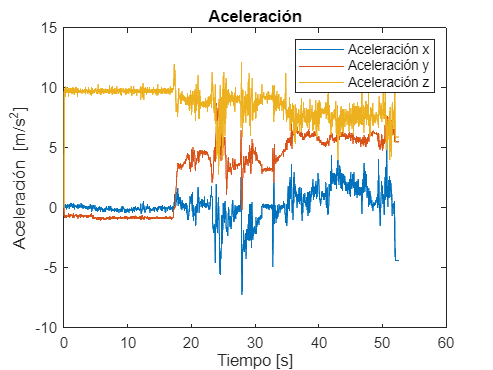

close all
clear all

% Abrir y decodificar el archivo json
file = 'Nicolas.json';
jsonText = fileread(file); 
data = jsondecode(jsonText);

% Obtener los valores 
values = data.payload.values;

% Vector de tiempo
t = 0:1/62.5:(length(values)-1)/62.5;

% Aceleración
acc_x = values(:,1);
acc_y = values(:,2);
acc_z = values(:,3);

figure;
plot(t,acc_x)
hold on
plot(t,acc_y)
plot(t,acc_z)
xlabel("Tiempo [s]")
ylabel("Aceleración [m/s^2]")
title("Aceleración")
legend("Aceleración x","Aceleración y","Aceleración z")
hold off

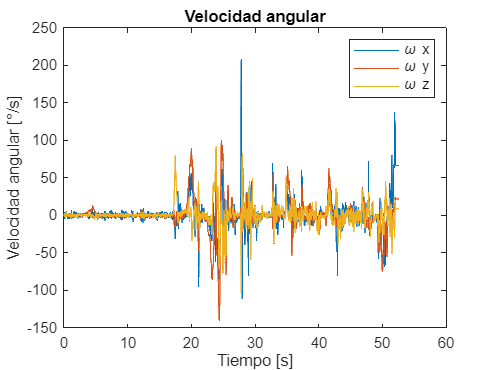


% Velocidad angular
w_x = values(:,4);
w_y = values(:,5);
w_z = values(:,6);

figure;
plot(t,w_x)
hold on
plot(t,w_y)
plot(t,w_z)
xlabel("Tiempo [s]")
ylabel("Velocidad angular [°/s]")
title("Velocidad angular")
legend("\omega x","\omega y","\omega z")
hold off

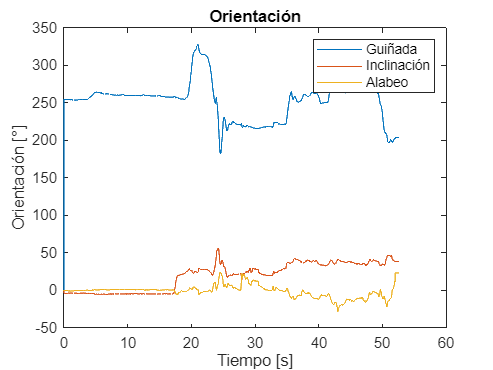


% Orientación
yaw = values(:,7);
pitch = values(:,8);
roll = values(:,9);

figure;
plot(t,yaw)
hold on
plot(t,pitch)
plot(t,roll)
xlabel("Tiempo [s]")
ylabel("Orientación [°]")
title("Orientación")
legend("Guiñada","Inclinación","Alabeo")
hold off

Acondicionamiento de senal

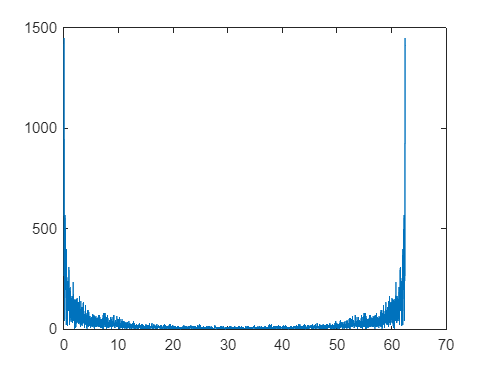

fft_ax = fft(acc_x);
fft_ay = fft(acc_y);
fft_az = fft(acc_z);

fft_wx = fft(w_x);
fft_wy = fft(w_y);
fft_wz = fft(w_z);

fft_y = fft(yaw);
fft_p = fft(pitch);
fft_r = fft(roll);

L = length(values);
plot(62.5/L*(0:L-1),abs(fft_ax)) % Magnitud

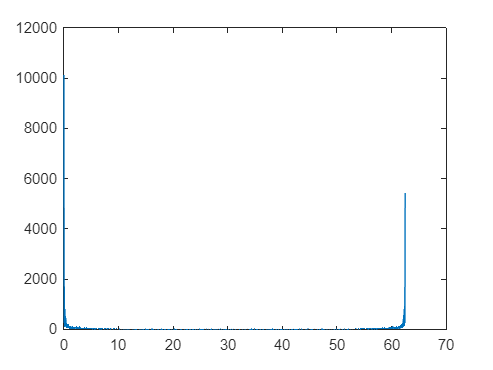

plot(62.5/L*(0:L-1),abs(fft_ay))

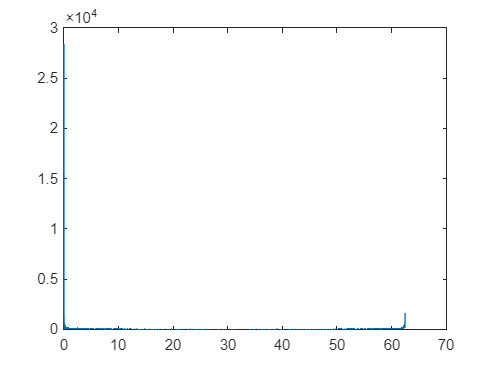

plot(62.5/L*(0:L-1),abs(fft_az))

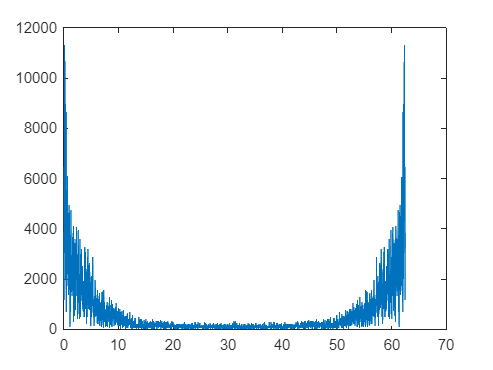


plot(62.5/L*(0:L-1),abs(fft_wx))

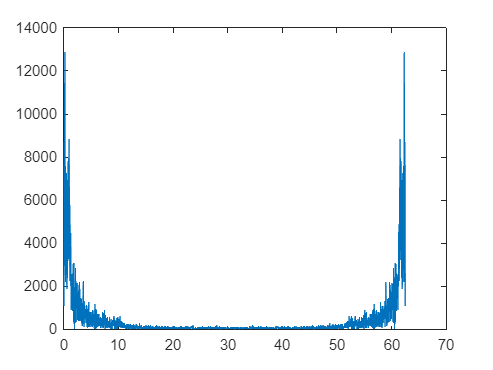

plot(62.5/L*(0:L-1),abs(fft_wy))

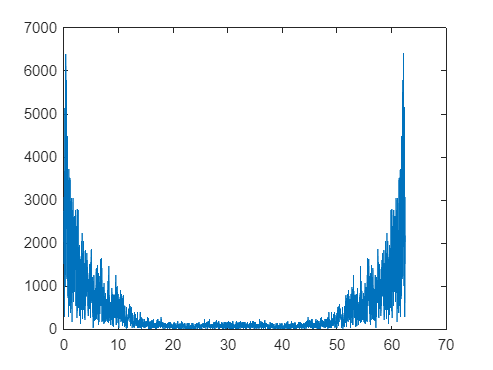

plot(62.5/L*(0:L-1),abs(fft_wz))

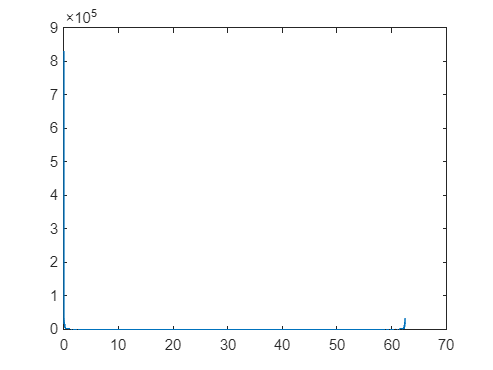


plot(62.5/L*(0:L-1),abs(fft_y))

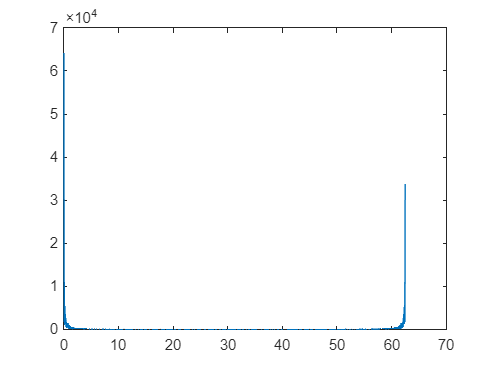

plot(62.5/L*(0:L-1),abs(fft_p))

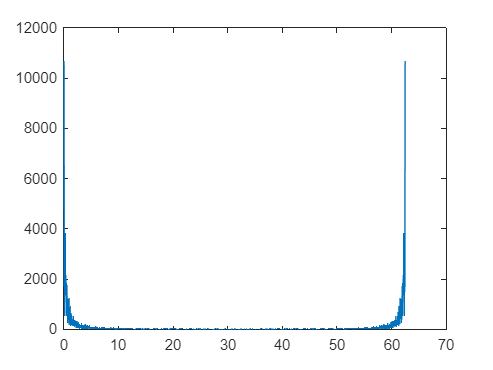

plot(62.5/L*(0:L-1),abs(fft_r))

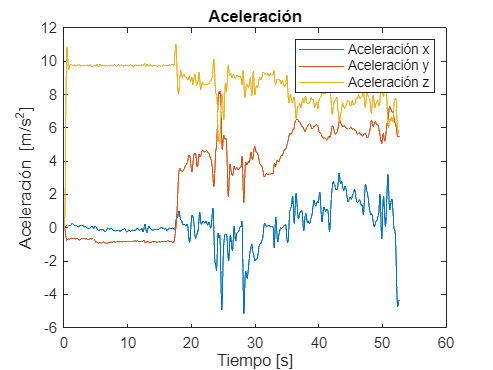


% Filtrado
cutoff1 = 2;
cutoff3 = 2;
cutoff5 = 2;
[b1,a1] = butter(4,cutoff1/(62.5/2),"low");
[b3,a3] = butter(4,cutoff3/(62.5/2),"low");
[b5,a5] = butter(4,cutoff5/(62.5/2),"low");

% Aceleración
acc_x_fil = filter(b5,a5,acc_x);
acc_y_fil = filter(b1,a1,acc_y);
acc_z_fil = filter(b1,a1,acc_z);
plot(t,acc_x_fil);
hold on
plot(t,acc_y_fil);
plot(t,acc_z_fil);
xlabel("Tiempo [s]")
ylabel("Aceleración [m/s^2]")
title("Aceleración")
legend("Aceleración x","Aceleración y","Aceleración z")
hold off

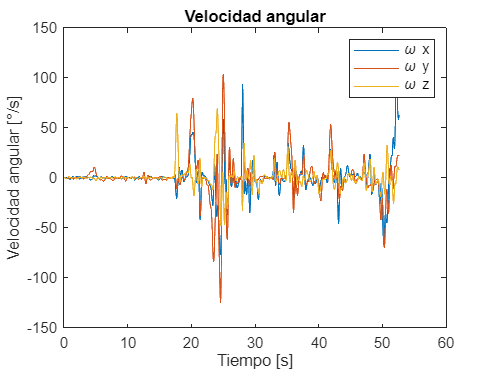


% Velocidad angular
w_x_fil = filter(b3,a3,w_x);
w_y_fil = filter(b5,a5,w_y);
w_z_fil = filter(b3,a3,w_z);

plot(t,w_x_fil)
hold on
plot(t,w_y_fil)
plot(t,w_z_fil)
xlabel("Tiempo [s]")
ylabel("Velocidad angular [°/s]")
title("Velocidad angular")
legend("\omega x","\omega y","\omega z")
hold off

Proyectar aceleracion a plano perpendicular a la gravedad

%Sacar el vectro de gravedad y su unitario
g_norm = ([acc_x_fil(20) acc_y_fil(20) acc_z_fil(20)])/norm([acc_x_fil(20) acc_y_fil(20) acc_z_fil(20)]);

%Matriz de aceleraciones
A = [acc_x_fil acc_y_fil acc_z_fil];

%Proyectar las aceleraciones a un plano perpendicular a g
%Ap = Ai - (Guni * Ai)Guni 

Ap = zeros(length(acc_x_fil),3);
for k = 1:length(acc_x_fil)
    Ap(k,:) = A(k,:) - (dot((g_norm),A(k,:))*g_norm); %Realizar esto una matriz
end

Proyectar velocidad angular a plano perpendicular a la gravedad

%Matriz de velocidad angular
W = [w_x_fil w_y_fil w_z_fil];

%Proyectar las velocidades angulares a un plano perpendicular a g

Wp = zeros(length(w_x_fil),3);
for k = 1:length(w_x_fil)
    Wp(k,:) = W(k,:) - (dot((g_norm),W(k,:))*g_norm); %Realizar esto una matriz
end

Verificacion para hallar la ventana inicial de aceleracion en x y

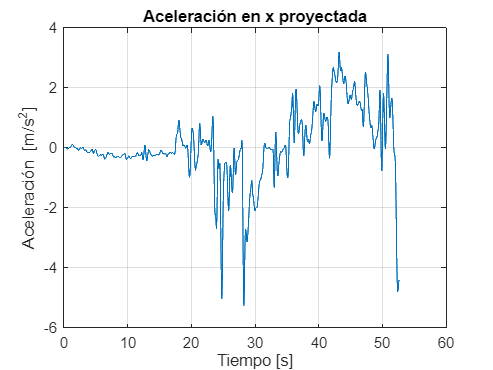

%verificacion para hallar la ventana inicial de aceleracion en x
figure;
plot(t,Ap(:,1))
ylabel('Aceleración [m/s^2]')
xlabel('Tiempo [s]')
title('Aceleración en x proyectada')
hold on;
grid on;

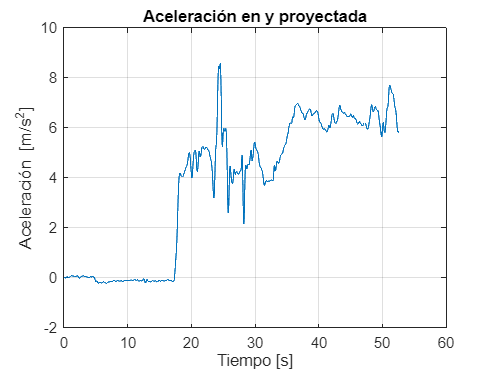


%verificacion para hallar la ventana inicial de aceleracion en y
figure;
plot(t,Ap(:,2))
grid on;
hold on;
ylabel('Aceleración [m/s^2]')
xlabel('Tiempo [s]')
title('Aceleración en y proyectada')
hold off;

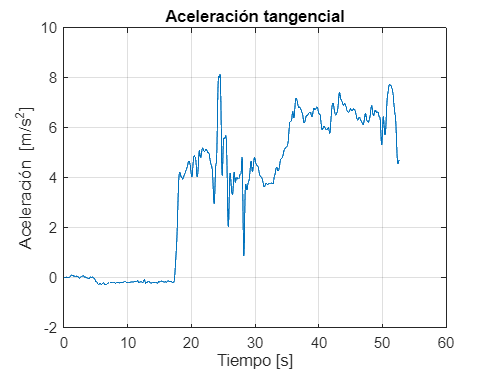

%Se debe hallar la aceleracion promecio en la ventana de aceleracion
%inicial para poder plantear Am y su unitario

Ay = zeros(1,(1136-1098));
for k = 1:(1136-1098) %posiciones de los datos tomados para la ventana
    Ay(k) = Ap(1098+k,2); %Realizar esto una matriz
end

Ax = zeros(1,(1136-1098)); %posiciones de los datos tomados para la ventana
for k = 1:(1136-1098)
    Ax(k) = Ap(1098+k,1); %Realizar esto una matriz
end

%Se saca el promedio de la ventana para hallar Am
Ay_m = mean(Ay);
Ax_m = mean(Ax);

%Se saca el unitario de A_m
A_m = ([Ax_m Ay_m])/(norm([Ax_m Ay_m]));

%Se halla la aceleracion tangencial

Ap(:,3) = [];
A_t = zeros(1,length(acc_x_fil));
for k = 1:(length(acc_x_fil))
   A_t(k) = dot(Ap(k,:),A_m); 
end

figure;
plot(t,A_t);
grid on;
hold on;
ylabel('Aceleración [m/s^2]')
xlabel('Tiempo [s]')
title('Aceleración tangencial')

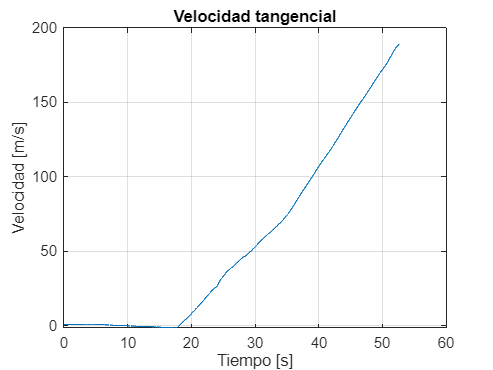

V = cumtrapz(t,A_t)+1; %Velocidad
figure;
plot(t,V);
grid on;
hold on;
ylabel('Velocidad [m/s]')
xlabel('Tiempo [s]')
title('Velocidad tangencial')

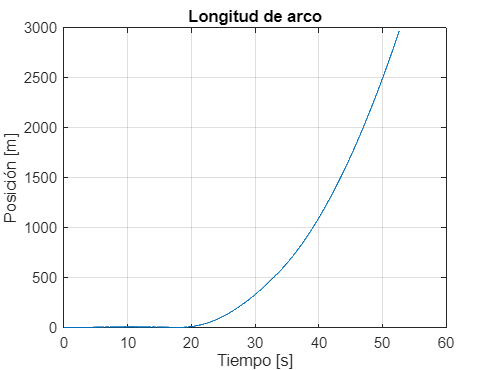

S = cumtrapz(t,V); %longitud de arco total hasta un t(i) 
figure;
plot(t,S);
grid on;
hold on;
ylabel('Posición [m]')
xlabel('Tiempo [s]')
title('Longitud de arco')
grid on;

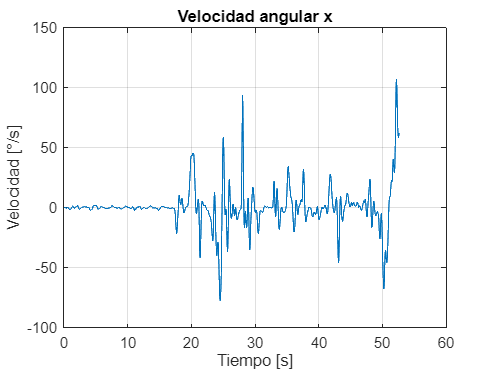

%Sacar el angulo 
figure;
plot(t,Wp(:,1)) %Velocidad angular
hold on;
grid on;
ylabel('Velocidad [°/s]')
xlabel('Tiempo [s]')
title('Velocidad angular x')

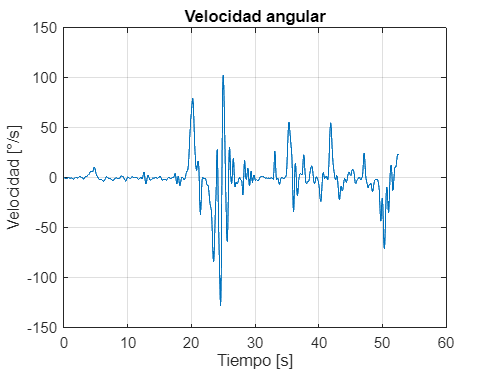


%Sacar el angulo 
figure;
plot(t,Wp(:,2))
grid on;
hold on;
ylabel('Velocidad [°/s]')
xlabel('Tiempo [s]')
title('Velocidad angular')

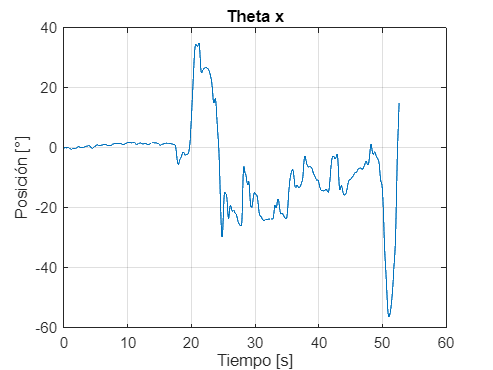


%Se halla las posiciones angulares
thetax = cumtrapz(t,(Wp(:,1))); %Posicion angular x
thetay = cumtrapz(t,(Wp(:,2))); %Posicion angular y

figure;
plot(t,thetax);
grid on;
title('Theta x')
ylabel('Posición [°]')
xlabel('Tiempo [s]')

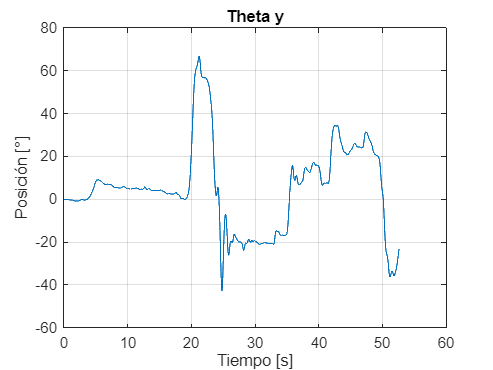


figure;
plot(t,thetay);
grid on;
title('Theta y')
ylabel('Posición [°]')
xlabel('Tiempo [s]')

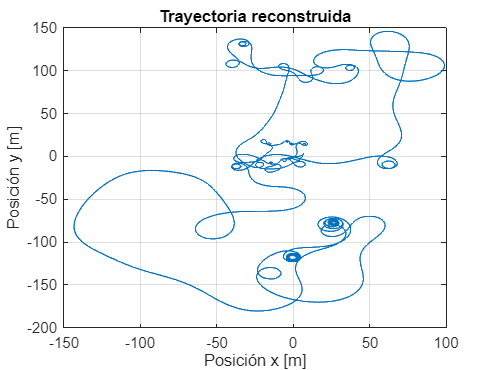


%Se intenta reconstruir la trayectoria
ds=diff(S); %distacia punto a punto
xn=zeros(2,length(acc_x_fil));
xn(:,1)= [0;0];

for i=1:length(t)-1
    xn(:,i+1)=xn(:,i)+ds(i)*[cos(thetax(i)); sin(thetax(i))];
end   

figure;
plot(xn(1,:),xn(2,:))
title('Trayectoria reconstruida')
ylabel('Posición y [m]')
xlabel('Posición x [m]')
hold on;
grid on;